#### Select subjects

clearvars;
filepath        = 'D:\Shrey\silent_wm_e02\ProcessedData\Artifact';
savepath        = 'D:\Shrey\silent_wm_e02\ProcessedData\LaplaceTests';
subjects        = CleanDir(filepath);

fakeUI          = figure;
fakeUI.UserData = subjects;
fakeUI.Visible  =  'off';
select_labels(fakeUI,[],subjects);
waitfor(findall(0,'Name','Select Labels'),'BeingDeleted','on');
subjects        = fakeUI.UserData;
close(fakeUI);

layout          = 'C:\Users\Rob Reinhart\Documents\GitHub\Deci\Function\Gen_Fun\easycap_rob_eye.mat';


**Hemi-field controlled posterior power analysis**

input dataset 1, 64 channels, 460 trials
input dataset 2, 64 channels, 479 trials
the channel order in the input-structures is not consistent, reordering
concatenating the trials over all datasets
reordering the channels back to the original input order
the input is raw data with 64 channels and 508 trials
Your data and configuration allow for multiple sensor definitions.
computing SCD for trial 508 of 508

output surface laplacian is in uV/m^2
the call to "ft_scalpcurrentdensity" took 39 seconds
the input is raw data with 60 channels and 508 trials
the call to "ft_redefinetrial" took 0 seconds
preprocessing
preprocessing trial 508 from 508

the call to "ft_preprocessing" took 2 seconds
the input is raw data with 60 channels and 508 trials
averaging trials
averaging trial 508 of 508

the call to "ft_timelockanalysis" took 0 seconds


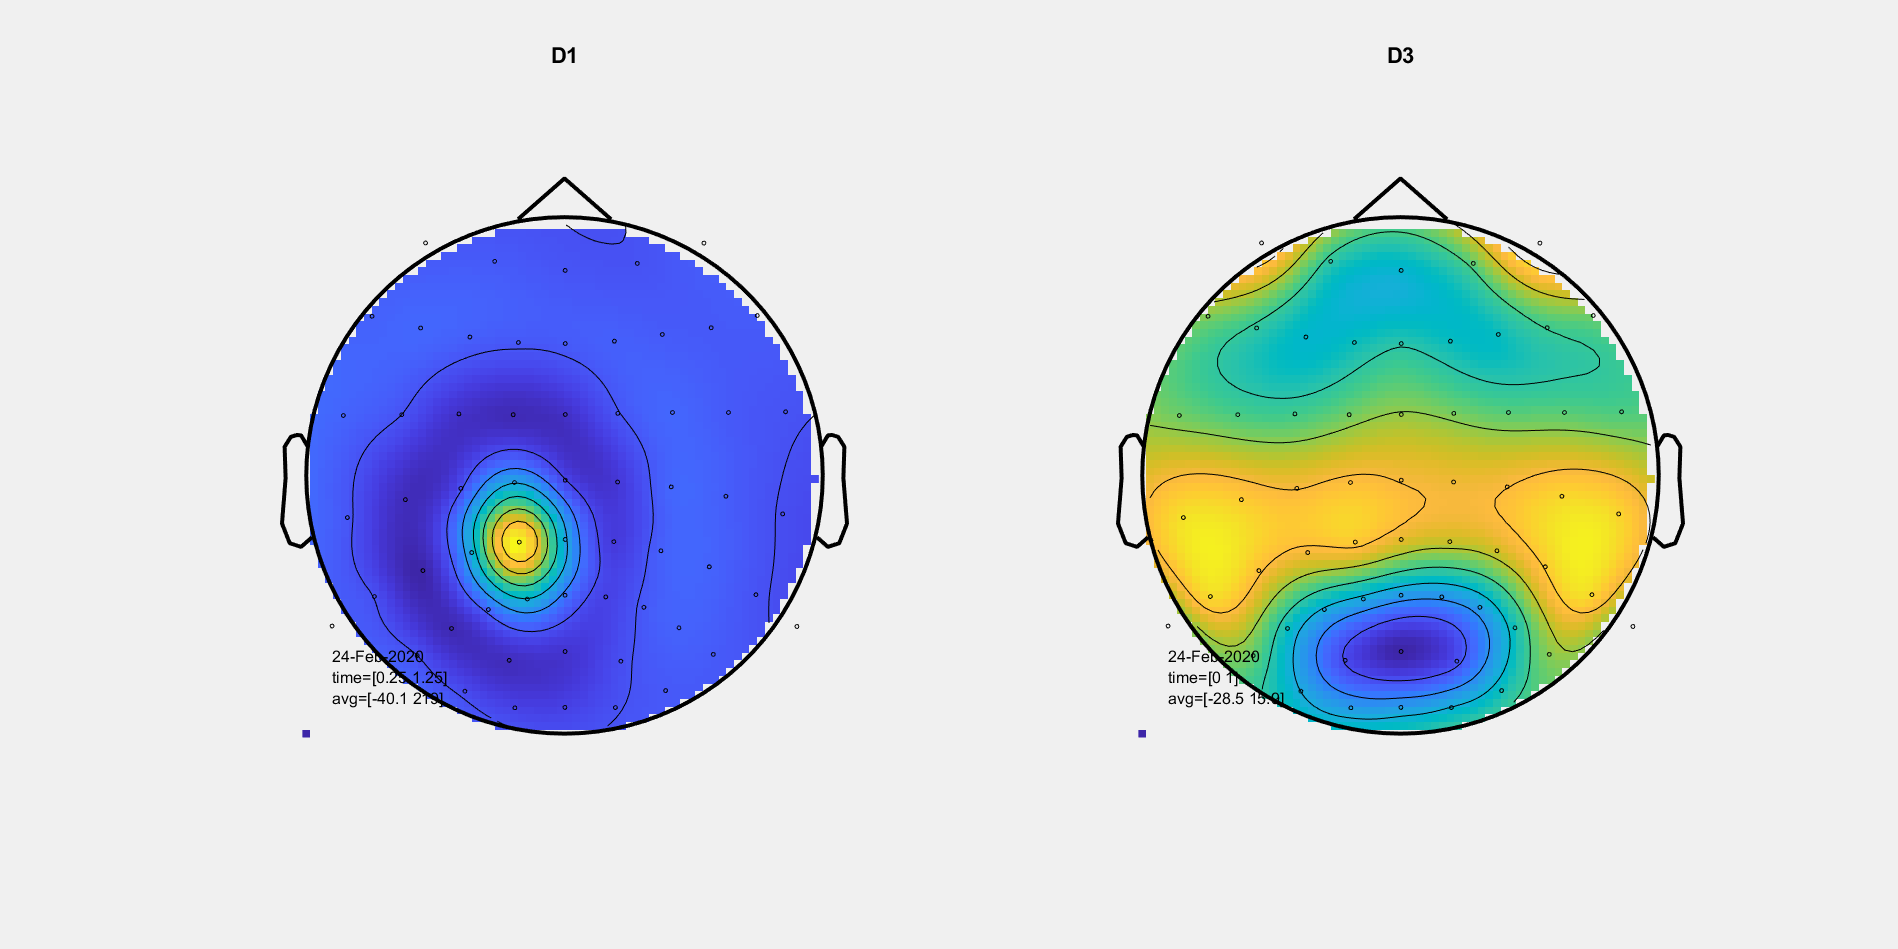

creating layout from data.elec
creating layout for eeg1010 system
the call to "ft_prepare_layout" took 0 seconds


the call to "ft_topoplotER" took 0 seconds
the input is raw data with 60 channels and 508 trials
the call to "ft_redefinetrial" took 0 seconds


preprocessing
preprocessing trial 508 from 508

the call to "ft_preprocessing" took 2 seconds
the input is raw data with 60 channels and 508 trials
averaging trials
averaging trial 508 of 508

the call to "ft_timelockanalysis" took 0 seconds
creating layout from data.elec
creating layout for eeg1010 system
the call to "ft_prepare_layout" took 0 seconds


the call to "ft_topoplotER" took 0 seconds
input dataset 1, 64 channels, 461 trials
input dataset 2, 64 channels, 472 trials
the channel order in the input-structures is not consistent, reordering
concatenating the trials over all datasets
reordering the channels back to the original input order
the input is raw data with 64 channels and 637 trials
Your data and configuration allow for multiple sensor definitions.


computing SCD for trial 637 of 637



output surface laplacian is in uV/m^2
the call to "ft_scalpcurrentdensity" took 49 seconds
the input is raw data with 60 channels and 637 trials
the call to "ft_redefinetrial" took 0 seconds
preprocessing
preprocessing trial 637 from 637

the call to "ft_preprocessing" took 2 seconds
the input is raw data with 60 channels and 637 trials
averaging trials
averaging trial 637 of 637

the call to "ft_timelockanalysis" took 0 seconds


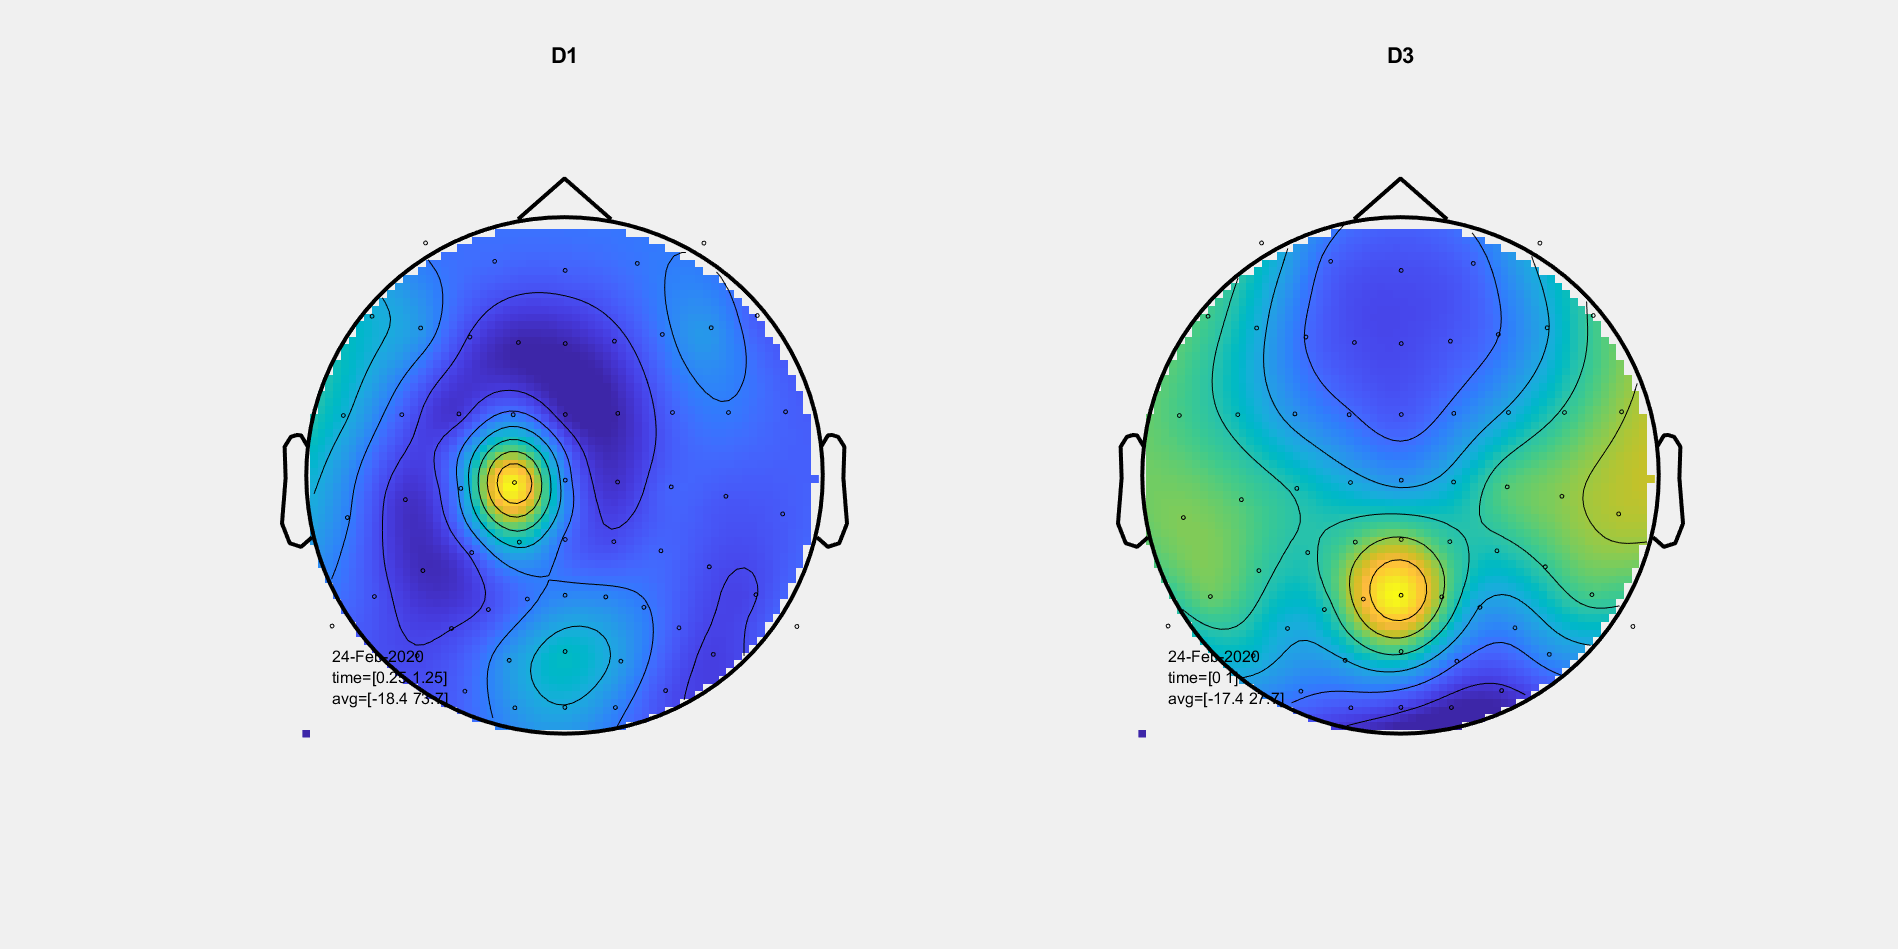

creating layout from data.elec
creating layout for eeg1010 system
the call to "ft_prepare_layout" took 0 seconds


the call to "ft_topoplotER" took 0 seconds
the input is raw data with 60 channels and 637 trials
the call to "ft_redefinetrial" took 0 seconds


preprocessing
preprocessing trial 637 from 637

the call to "ft_preprocessing" took 2 seconds
the input is raw data with 60 channels and 637 trials
averaging trials
averaging trial 637 of 637

the call to "ft_timelockanalysis" took 0 seconds
creating layout from data.elec
creating layout for eeg1010 system
the call to "ft_prepare_layout" took 0 seconds


the call to "ft_topoplotER" took 0 seconds


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% type of data to analyse 
version = [];
cipower.dataprep.hemi           = true;
cipower.dataprep.correct        = true;
cipower.dataprep.incorrect      = false;
cipower.dataprep.laplace        = true;
cipower.dataprep.locks          = [1 2]; % [1],[2],[3],[1 2],[1 2 3]; as of now I only need locks 1 and 2 (stim onset and d3 onset)
cipower.dataprep.cutlatency     = [-1 5];

% frequency decomposition parameters
cipower.decompose.freq          = 2:50; 
cipower.decompose.width         = linspace(3,13,length(cipower.decompose.freq));
cipower.decompose.time          = -0.05:0.001:1.25;
cipower.decompose.bstoi         = [-0.2 0];
cipower.decompose.output        = 'pow';
cipower.decompose.keeptrials    = 'no';

% cipower.decompose.chan          = {'AF7', 'AF3', 'AFz','AF4','AF8','F7','F5','F3','F1','Fz','F2','F4','F6','F8','FT7','FC5','FC3','FC1','FCz','FC2','FC4','FC6','FT8','T7','C5','C3','C1','Cz','C2','C4','C6','T8','TP7','CP5','CP3','CP1','CPz','CP2','CP4','CP6','TP8','P7','P5',...
% 'P3','P1','Pz','P2','P4','P6','P8','PO7','PO3','POz','PO4','PO8','O1','Oz','O2'};
cipower.decompose.chan          = {'P7','P5','P3','P1','Pz','P2','P4','P6','P8','PO7','PO3','POz','PO4','PO8','O1','Oz','O2'};
% cipower.decompose.chan          = {'PO7','PO3','PO4','PO8','O1','O2'};
cipower.decompose.hilbert       = false; % if unchecked, wavelet decomposition will be run by default (width=3:13; gwidth=4).

cipower.baseline = cipower.decompose;
cipower.baseline.time = -0.2:0.001:0;

% Call the subroutine
PCom                            = false;         
if exist('PComs') == 0 && PCom
    PComs(1) = parfeval(@rand,0,1);
end

if PCom == true
    for subject= 1:length(subjects)
        director = [filepath filesep subjects{subject} filesep subjects{subject}];
        PComs(end+1)= parfeval(@laplace_test_subroutine,0,subjects{subject},filepath,savepath,version,cipower);
    end
else
    for subject= 1:length(subjects)
        director = [filepath filesep subjects{subject} filesep subjects{subject}];
        laplace_test_subroutine(subjects{subject},filepath,savepath,version,cipower);
    end
end